# Digital Control Design

#### Twin Rotor MIMO System

Kashirin Aleksandr

The aim of the project is designing the compensator based on the linearized model of the TRMS to control a nonlinear model of the actual TRMS.

1) Workspace cleaning

close all;
clear;
clc;

2) File control flags

% Plots and graphs
PlotLinearization = 1;                              % Flag to control linearization plots
PlotVerification = 1;                               % Flag to control verificaton plot
PlotPZmap = 1;                                      % Flag to control PZplot

3) Model parameters

% Discretization time
Ts = 0.01;

% Reference signals, consider reference signals: angles
RefV = deg2rad(-5);                                 % RefV, Coordinate for AlphaV [rad]
RefH = deg2rad(5);                                  % RefV, Coordinate for AlphaH [rad]

% Linearization point is the point where we would like to control our system
U0m = 18;                                           % U0m, Main rotor output voltage [V]
U0t = 4;                                            % U0t, Tail rotor output voltage [V]

% Initial conditions
% Consider initial conditions for the system simulation
Wm_init = 0;                                        % Initial rotating velocity of the Main rotor [rad/s]
Wt_init = 0;                                        % Initial rotating velocity of the Tail rotor [rad/s]
AlphaV_init = deg2rad(-37.5);                       % Initial vertical angle [rad]
AlphaH_init = 0;                                    % Initial horizontal angle [rad]
OmegaV_init = 0;                                    % Initial angular vertical velocity [rad/s]
OmegaH_init = 0;                                    % Initial angular horizontal velocity [rad/s]

Exercise 1: DC-motor and aerodynamical parameters

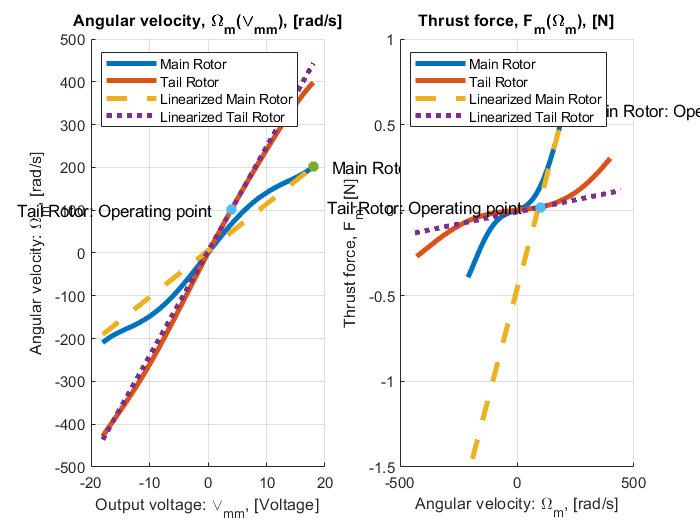

load polynom %  THIS FILE INCLUDE THE POLYNOMIALs FITTED FOR THE EXPERIMENTAL DATA

%DATA NEEDED FOR THE SIMULATION MODEL
P_motor_m=polynom.MainSpeed;            % POLYNOMIAL FROM VOLTAGE TO ANGULAR VELOCITY (main rotor)
F_aero_m=polynom.MainForce;             % POLYNOMIAL FROM ANGULAR VELOCITY TO FORCE(main rotor)
P_motor_t=polynom.TailSpeed;            % POLYNOMIAL FROM VOLTAGE TO ANGULAR VELOCITY (tail rotor)
F_aero_t=polynom.TailForce;             % POLYNOMIAL FROM VOLTAGE ANGULAR VELOCITY TO FORCE(tail rotor)

%Analyze the nonlinear dynamics (use polyval to obtain angular velocity and plot the data)
um=-18:0.1:18;                          % VOLTAGE RANGE UNDER STUDY for main rotor
Wm = polyval(P_motor_m, um);
Wt = polyval(P_motor_t, um);

%Use angular velocity obtained above and analyze the dynamics from
%velocity to force (use the F_aero data and polyval function again)
Fm = polyval(F_aero_m, Wm);
Ft = polyval(F_aero_t, Wt);

% Calculate Jacobian Linearization:
Kum = polyval(P_motor_m, U0m) + polyval(polyder(P_motor_m), U0m)*(um-U0m);
K_um = polyval(polyder(P_motor_m), U0m);     % K_um - Incline coefficient 
Kut = polyval(P_motor_t, U0t) + polyval(polyder(P_motor_t), U0t)*(um-U0t);
K_ut = polyval(polyder(P_motor_t), U0t);     % K_ut - Incline coefficient 

% Calculate operating Y0, Y1 - Angular velocity;
Y0 = polyval(P_motor_m, U0m);           % Main rotor
Y1 = polyval(P_motor_t, U0t);           % Tail rotor

% Calculate Jacobian Linearization:
Kam = polyval(F_aero_m, Y0) + polyval(polyder(F_aero_m), Y0)*(Kum-Y0);
K_am = polyval(polyder(F_aero_m), Y0);  % K_am - Incline coefficient
Kat = polyval(F_aero_t, Y1) + polyval(polyder(F_aero_t), Y1)*(Kut-Y1);
K_at = polyval(polyder(F_aero_t), Y1);  % K_at - Incline coefficient

if PlotLinearization
    % Plot the graphics
    figure('Name', 'Linearization');
    subplot(1,2,1);
    hold on;
    plot(um,Wm,'LineWidth',3);
    plot(um,Wt,'LineWidth',3);
    plot(um,Kum,'--','LineWidth',3);
    plot(um,Kut,':','LineWidth',3);
    plot(U0m,Y0, '*', 'LineWidth', 3);       % Main Rotor operating point
    plot(U0t,Y1, '*', 'LineWidth', 3);       % Tail Rotor operating point
    hold off;
    grid on;
    title("Angular velocity, \Omega_{m}(\vee_{mm}), [rad/s]")
    ylabel("Angular velocity: \Omega_{m}, [rad/s]");
    xlabel("Output voltage: \vee_{mm}, [Voltage]");
    legend('Main Rotor','Tail Rotor', 'Linearized Main Rotor', 'Linearized Tail Rotor','Location','northwest');
    text(U0m,Y0,'    Main Rotor: Operating point    ');
    text(U0t,Y1,'    Tail Rotor: Operating point    ', 'HorizontalAlignment','right');

    subplot(1,2,2);
    hold on;
    plot(Wm, Fm,'LineWidth',3);
    plot(Wt, Ft,'LineWidth',3)
    plot(Kum, Kam,'--','LineWidth',3);
    plot(Kut, Kat,':','LineWidth',3);
    plot(Y0, polyval(F_aero_m, Y0), '*', 'LineWidth', 3);       % Main Rotor operating point
    plot(Y1, polyval(F_aero_t, Y1), '*', 'LineWidth', 3);       % Tail Rotor operating point
    hold off;
    grid on;
    title("Thrust force, F_{m}(\Omega_{m}), [N]")
    ylabel("Thrust force, F_{m}, [N]");
    xlabel("Angular velocity: \Omega_{m}, [rad/s]");
    legend('Main Rotor','Tail Rotor','Linearized Main Rotor', 'Linearized Tail Rotor','Location','northwest');
    text(Y0, polyval(F_aero_m, Y0),'    Main Rotor: Operating point    ');
    text(Y1, polyval(F_aero_t, Y1),'    Tail Rotor: Operating point    ', 'HorizontalAlignment','right');
end

Exercise 2: Dynamic part modeling

g = 9.81;

% Component masses
m_m = 0.0145;               % m_m, Mass of the main beam [kg]
m_t = 0.0155;               % m_t, Mass of the tail beam [kg]
m_b = 0.022;                % m_b, Mass of the counterweight beam [kg]
m_tr = 0.206;               % m_tr, Mass of the tail motor [kg]
m_cb = 0.068;               % m_cb, Mass of the counterweight [kg]
m_ts = 0.165;               % m_ts, Mass of the tail rotor shield [kg]
m_ms = 0.225;               % m_ms, Mass of the main rotor shield [kg]
m_mr = 0.228;               % m_mr, Mass of the main motor [kg]

% Dimensions
l_m = 0.24;                                     % l_m, Lenght of the main beam [m]
l_t = 0.25;                                     % l_t, Length of the tail beam [m]
l_b = 0.26;                                     % l_b, Length of the counterweight beam[m]
l_cb = 0.26;                                    % l_cb, Position of the counterweight [m]
r_ts = 0.1;                                     % r_ts, Radius of the tail shield [m]
r_ms = 0.155;                                   % r_ms, Radius of the main shield [m]

% Compact components
A=(m_t/2+m_tr+m_ts)*l_t;
B = (m_m/2+m_mr+m_ms)*l_m;
C = (m_b/2*l_b+m_cb*l_cb);
E = (m_m/3+m_mr+m_ms)*l_m^2+(m_t/3+m_tr+m_ts)*l_t^2;
F = m_ms*r_ms^2+m_ts/2*r_ts^2;
D = (m_b/3*l_b^2+m_cb*l_cb^2);

%==========================================================================
%INERTIAT VERTICAL
%==========================================================================
% Vertical
Jv1=m_mr*l_m^2;                                 % Jv1, Inertia of the main rotor (simplified) [kg*m^2]
Jv2=m_m*l_m^2/3;                                % Jv2, Inertia of the main beam [kg*m^2]
Jv3=m_cb*l_cb^2;                                % Jv3, Inertia of the counterweight (simplified) [kg*m^2]
Jv4=m_b*l_b^2/3;                                % Jv4, Inertia of the beam [kg*m^2]
Jv5=m_tr*l_t^2;                                 % Jv5, Inertia of the tail rotor [kg*m^2]
Jv6=m_b*l_b^2/3;                                % Jv6, Inertia of the tail beam [kg*m^2]
Jv7=m_ms*(r_ms^2/2+l_m^2);                      % Jv7, Inertia of the main shield [kg*m^2]
Jv8=m_ts*(r_ts^2+l_t^2);                        % Jv8, Inertia of the tail shield [kg*m^2]
J_v=Jv1+Jv2+Jv3+Jv4+Jv5+Jv6+Jv7+Jv8;            % Jv, Total vertical moment of inertia [kg*m^2]

% Horizontal components are depended on the angle, we are counting it in the Simulink

% Cross-coupling part
J_tr = 1.654e-5;                                % J_tr, Inertia of the tail propeller [kg*m^2]
J_mr = 2.65e-5;                                 % J_mr, Inertia of the main propeller [kg*m^2]
 
k_h = 0.0095;                                   % k_h, Horizontal friction coefficient [Nms/rad]       
k_v = 0.00545;                                  % k_v, Vertical friction coefficient [Nms/rad]  

% Motor constants
Tm = 0.8921;                                    % Motor time constant of main rotor
Tt = 0.3423;                                    % Motor time constant of tail rotor


Exercise 3: Linearization

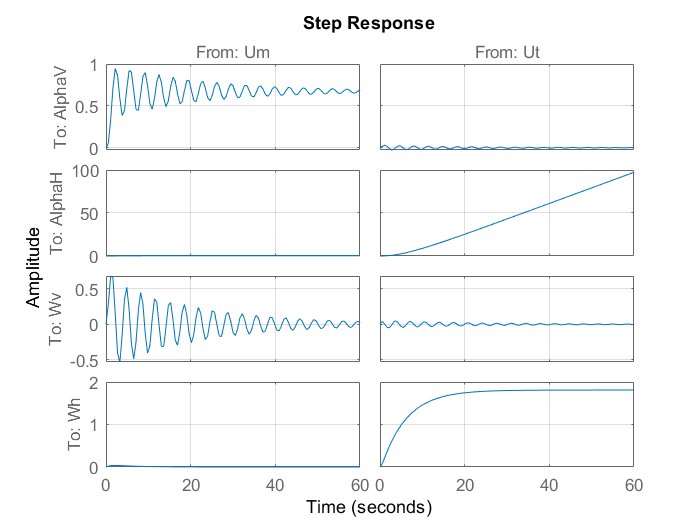


% System Verification
Aver = [-1/Tm 0 0 0 0 0                % A - System dynamics
        0 -1/Tt 0 0 0 0
        0 0 0 0 1 0
        0 0 0 0 0 1
        l_m*K_am/J_v -J_tr/(J_v*Tt) -g*C/J_v 0 -k_v/J_v 0
        -J_mr/((E+F)*Tm) l_t*K_at/(E+F) 0 0 0 -k_h/(E+F)]; 

Bver = [K_um/Tm 0                      % B - Input gain
        0 K_ut/Tt
        0 0
        0 0
        0 J_tr*K_ut/(J_v*Tt)
        J_mr*K_um/((E+F)*Tm) 0];
 
Cver = [0 0 1 0 0 0
        0 0 0 1 0 0
        0 0 0 0 1 0
        0 0 0 0 0 1];                  % C - Output gain

Dver = [0 0
        0 0
        0 0
        0 0];                          % D - Feedthrough matrix

sysVerification = ss(Aver,Bver,Cver,Dver,'StateName',{'Wm' 'Wt' 'AlphaV' 'AlphaH' 'Wv' 'Wh'}, ...
    'InputName',{'Um' 'Ut'}, 'OutputName', {'AlphaV' 'AlphaH' 'Wv' 'Wh'}');


% Plot the step response
if PlotVerification
    figure('Name','System Verification');
    opt = stepDataOptions;
    opt.StepAmplitude = 10;
    step(sysVerification, 60, opt);  % step-response of the verification system
    grid on;
end

% Actual continuous linearised system
% According to the first lecture we can measure Wt, Wm, Pitch and Yaw

Ac = Aver;                          % A - System dynamics

Bc = Bver;                          % B - Input gain

Cc = [1 0 0 0 0 0
      0 1 0 0 0 0
      0 0 1 0 0 0
      0 0 0 1 0 0];                 % C - Output gain

Dc = Dver;                          % D - Feedthrough matrix

sysC = ss(Ac,Bc,Cc,Dc,'StateName',{'Wm' 'Wt' 'AlphaV' 'AlphaH' 'Wv' 'Wh'}, ...
    'InputName',{'Um' 'Ut'}, 'OutputName', {'Wm' 'Wt' 'AlphaV' 'AlphaH'});

% Actual discrete linearised system
sysD = c2d(sysC,Ts);
[Phi,Gam,Cd,Dd] = ssdata(sysD);

Exercise 4: Controller design

% Step 1: Observability
% We want to know if we can estamite or observe our missing states that we
% can not measure directly. For this purpose we can check the observability
% matrix of our original system.
disp('Observability of the original system');

Observability of the original system


Wo = obsv(Phi,Cd);
if rank(Wo) == length(Phi)
    disp('The system is observable!');
    disp(' ');
    
    % Step 2: Adding observable states to the system
    % We consider that we can measure all the states by the system output
    % because later we are going to synthesise an estimator that can estimate
    % missing states

    Cd_all = [1 0 0 0 0 0
              0 1 0 0 0 0
              0 0 1 0 0 0
              0 0 0 1 0 0
              0 0 0 0 1 0
              0 0 0 0 0 1];                 % C - Output gain

    Dd_all = zeros(6,2);                    % D - Feedthrough matrix

    sysD_all = ss(Phi,Gam,Cd_all,Dd_all, Ts,'StateName',{'Wm' 'Wt' 'AlphaV' 'AlphaH' 'Wv' 'Wh'}, ...
        'InputName',{'Um' 'Ut'}, 'OutputName', {'Wm' 'Wt' 'AlphaV' 'AlphaH' 'Wv' 'Wh'});
    
    % Step 4: Adding the integrating actions
    % We want to get rid off the steady-state error for our measured angles, so
    % we need to add two additional states. But here we have to notice that we
    % augment the system only for two additional states, not for six. So we
    % need to extract reauired outputs from the system, which are AlphaV and AlphaH

    Phi_aug = [Phi zeros(6,2)
               Cd_all(3:4,1:6) eye(2,2)];

    Gam_aug = [Gam
               zeros(2,2)];

    Cd_aug = [Cd_all zeros(6,2)
              zeros(2,6) eye(2,2)];

    Dd_aug = zeros(8,2);

    sysD_aug = ss(Phi_aug,Gam_aug,Cd_aug,Dd_aug, Ts,'StateName',{'Wm' 'Wt' 'AlphaV' 'AlphaH' 'Wv' 'Wh' 'Int_Err_V' 'Int_Err_H'}, ...
        'InputName',{'Um' 'Ut'}, 'OutputName', {'Wm' 'Wt' 'AlphaV' 'AlphaH' 'Wv' 'Wh' 'Int_Err_V' 'Int_Err_H'});
    
    % Step 5: Controllability
    % Controllability says us that system can be controlled and allows us to
    % design the controller for the specified system.
    disp('Controllability of the augmented system:');
    Wc = ctrb(Phi_aug,Gam_aug);
    
    if rank(Wc) == length(Phi_aug)
        disp('The system is controllable!');
        
        % Step 6: LQR Controller
        
        % Designing the discrete LQR
        % Weight matrices: Q1 - response behavior, Q2 - input usage aggressiveness
        
        % Weights for the Q1 and Q2
        m1 = 5;                       % m1 - max deviation of Wm [rad/s]
        m2 = 3;                        % m2 - max deviation of Wt [rad/s]
        m3 = deg2rad(0.2);               % m3 - max deviation of AlphaV [rad]
        m4 = deg2rad(0.2);             % m4 - max deviation of AlphaH [rad]
        m5 = 1;                    % m5 - max deviation of OmegaV [rad/s]
        m6 = 1;                   % m6 - max deviation of OmegaH [rad/s]
        % Integral errors
        m7 = 0.3;                      % m7 - max deviation of AlphaV error integral [rad*s] 
        m8 = 0.3;                     % m8 - max deviation of AlphaH error integral [rad*s]
        % Inputs
        u1 = 0.15;                         % u_max - max deviation of input voltage [V]
        u2 = 0.25;
        
        Q1 = diag([1/m1^2 1/m2^2 1/m3^2 1/m4^2 0 0 1/m7^2 1/m8^2]);   % Q1 - response behavior
        
        Q2 = diag([1/u1^2 1/u2^2]);                % Q2 - input usage aggressiveness
          
        % LQR controller 
        [K, S, e] = dlqr(Phi_aug, Gam_aug, Q1, Q2);  
        K_fsfb = K(1:2, 1:6);           % Feedback part
        K_int = K(1:2, 7:8);             % Integral part
        
        % Eigenvalues of the closed-loop system
        Eig = eig(Phi_aug - Gam_aug*K);        

        % Step 7: Dynamics of the closed-loop system
        % Let us check the system dynamics without LQR controller and with
        % it. Our goals is to minimize setling times, get rid off overshooting 
        if PlotPZmap == 1
            figure('Name', 'Poles of the systems');
            opt = pzoptions;
            opt.Grid = 'on';
            opt.IOGrouping = 'all';
            opt.Xlim = [0.9 1.04];
            opt.Ylim = [-0.04 0.04];
            pzplot(sysD_aug, feedback(sysD_aug,K), opt);
            legend('Open-loop','Controller');
        end

        Exercise 5: Estimator design 

The system is observable!


Controllability of the augmented system:


The system is controllable!


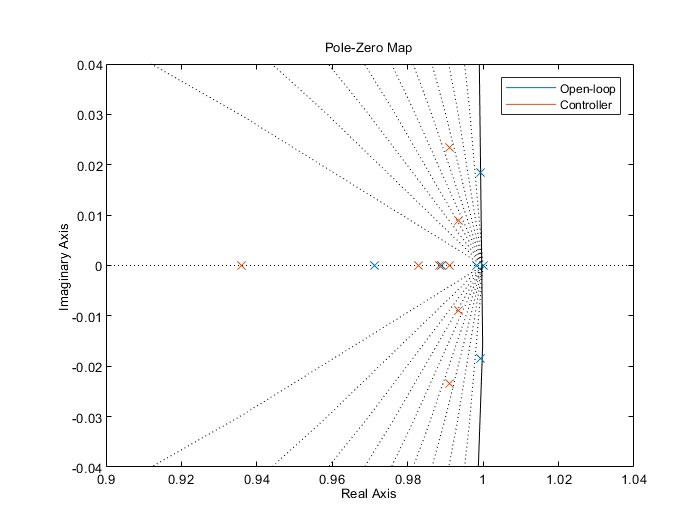

The system is not controllable, next procedures are not required.


        % Poleplacement design
        controlPoles = sort(Eig);
        poles = controlPoles(1:6,1).^10;
        L = place(Phi',Cd',poles).';
        
        disp('The system is not controllable, next procedures are not required.');
    end
else
    disp('The system is not observable, next procedures are not required.');
end